# Polynomial Spectra

## Here's an idea.

Why not model signals of interest with a non-constant, a-periodic sinusoidal waveform?

x^4+3*x^3+8x^2+1 = 0

[`y`](https://www.mathworks.com/help/matlab/ref/polyval.html?searchHighlight=polyval&s_tid=srchtitle_polyval_1#d124e1212967) `=` `polyval``(`[`p`](https://www.mathworks.com/help/matlab/ref/polyval.html?searchHighlight=polyval&s_tid=srchtitle_polyval_1#f93-999699_sep_shared-p)`,`[`x`](https://www.mathworks.com/help/matlab/ref/polyval.html?searchHighlight=polyval&s_tid=srchtitle_polyval_1#d124e1212820)`)` evaluates the polynomial `p` at each point in `x`. The argument `p` is a vector of length `n+1` whose elements are the coefficients (in descending powers) of an `n`th-degree polynomial:


x=-1e6:100000:1e6; % the indepedent variable is -1e6 to 1e6 
                 % with a step size of 1000

p = [1 3 8 1] % polynomial coefficients are listed

p =      1     3     8     1


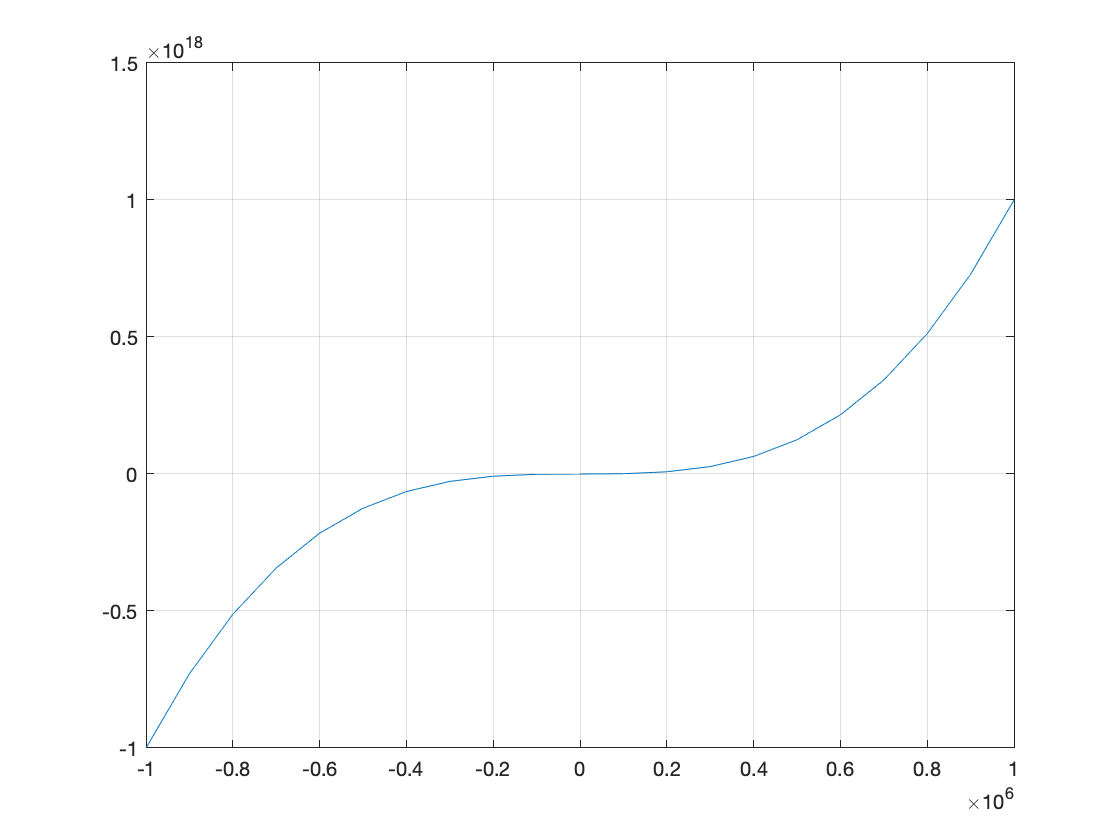

plot(x,polyval(p,x)) % we plot the polynomial vs. input
grid on % plot has grid lines